# Lab session IV:

## Intro:

On this Laboratory session we are going to work with the different attitude representations seen in class. 

- Exercise 1: 1 point. To be delivered before the end of the session.

- Exercise 2: 3 points

- Exercise 3: 3 points

- Exercise 4: 3 points

**Lab rules:**

- Always respect the delivery dates

- Use the templates when provided and DO NOT MODIFY THE FILE NAMES OR THE FUNCTION NAMES

- Verify that your code works before submit

- Always upload the files in a .zip with the name structure:  * Surname_Name.zip*

- Cheating is not allowed and will be firmly punished with a final mark of 0 

This assignment is due to 

# Exercise 1:

The point p has coordinates

p_A = [3, 4]';

on a frame {A}, and coordinates

p_B = [-2.5, 0.5]';

on a frame {B}.

It is known that the angle between $x$-axis of frame {A} and the$y$ axes of the frame {B} is 30 deg counterclockwise.

##  1.1 Which are the coordinates of the origin of A seen from B?

bRa = [cosd(60), -sind(60); sind(60), cosd(60)]

bRa =     0.5000   -0.8660
    0.8660    0.5000


%Demostració de bRa -> el vector que conforma l'eix canònic X a la base A (1;0) 
%té coordenades positives en X i Y de la base B
xa = [1;0];
xb = bRa * xa

xb =     0.5000
    0.8660


%SOLUCIÓ
BdBA = -bRa * p_A + p_B

BdBA =    -0.5359
   -4.0981


##  1.2 Which are the coordinates of the origin of B seen from A?

aRb = bRa';
AdAB = -aRb * p_B + p_A

AdAB =     3.8170
    1.5849


##  1.3 Which are the coordinates of a point q expressed in A if 

q_B = [3,1]';
q_A = aRb * q_B + AdAB

q_A =     6.1830
   -0.5131


# Exercise 2:

 Let {A}, {B} and {C}, be 3 different reference frames. From them we know that:

- The origin of B with respect A is

AoB = [3,1,-2]';

- The origin of C with respect B is

BoC = [-3, 1,-2]';

- The three frames has different orientations in space. In fact:  

- The set of Euler angles stored in $\eta$ as $\eta = (\psi,\theta,\phi)$

eta = [25;145;30]; % Expressed in degrees

                 represent 3 consecutive rotations about z, y, and x respectively that allows to transform vectors from {A} to {B}

- The quaternion

q = 1/7*[-sqrt(3)*3.5;3;-1;-1.5];

                 allows to express in {B} a vector defined in {C}, if {C} and {B} had the same origin

Let in addition v1 and v2 to be points which coordinates are known in  {C}.

v1_C = [0;2;0];
v2_C = [0;2;5];

With the information provided above determine:

##  2.1.1 The affine** expression** that allows to relate a vector originally given in {C} to {B}. Note that no calculations have to be provided here, only the expression which is not a matrix.

- v_B = bRc * v_C + BdBC

- v_B -> vector expressat en base B

- bRc -> matriu de rotació per passar de base C a base B

- v_C -> vector expressat en base C

- BdBC -> vector que descriu la posició de l'origen de C vist des de B

## 2.1.2 Implement a function called rotVbyq that provided a vector and a quaternion rotates the vector using quaternion multiplications. Test it and commet why do you think it is well implemented.

%inventem un vector per les comprovacions i el rotem 90 graus en Z
vector = [1; 0; 0];
quat = [cos(pi/4); 0; 0; sin(pi/4)];

rotated_vector = rotVbyq(vector, quat)

rotated_vector =     0.0000
    1.0000
         0


%el vector que hem agafat és la X canònica i per tant, al rotar-la 90 graus en Z
%hauria de resultar el vector Y canònic. És justament el què passa i per tant concloem
%que la funció està ben implementada.

##  2.2 The affine matrix that allows to express a vector originally given in {C} to {A}.

%matrius de rotació per anar de C a B i de A a B
bRc = Quat2rotM(q);
bRa = eAngles2rotM(eta(1), eta(2), eta(3));

%construïm aRc
aRc = bRa' * bRc;

%origen de C vist des d'A
AoC = bRa' * BoC + AoB

AoC =     5.8658
    3.3281
   -2.6058



%matriu afí
aAc = zeros(4,4);
aAc(1:3, 1:3) = aRc;
aAc(1:3, 4) = AoC;
aAc(4,4) = 1;

aAc

aAc =    -0.4699    0.5193   -0.7138    5.8658
    0.1636    0.8459    0.5077    3.3281
    0.8674    0.1218   -0.4824   -2.6058
         0         0         0    1.0000


## 2.3 The vectors v1_C and v2_C forms a segment. Make a 3d plot (plot3() in matlab), representing how the segment is seen on {A} in red, on {B} in blue and on {C} in green.

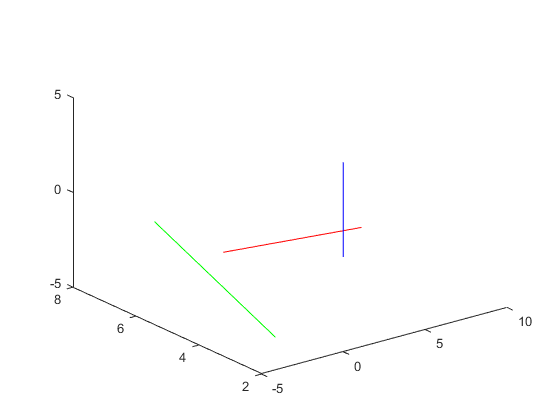

%A
v1_A = aAc * [v1_C; 1];
v2_A = aAc * [v2_C; 1];


plot3([v1_A(1) v2_A(1)], [v1_A(2) v2_A(2)], [v1_A(3) v2_A(3)], 'r');

%B
v1_B = bRc * v1_C + BoC;
v2_B = bRc * v2_C + BoC;

hold on;

plot3([v1_B(1) v2_B(1)], [v1_B(2) v2_B(2)], [v1_B(3) v2_B(3)], 'g');

%C

hold on;

plot3([v1_C(1) v2_C(1)], [v1_C(2) v2_C(2)], [v1_C(3) v2_C(3)], 'b');

hold off;

# Exercise 3:

The points described by the columns of the matrix A 

A = load('AEx3.mat');
A = A.A;

are points contained into a circle, and they are defined in a world frame W.

A camera is situated at point

wc = [1; 6; 1];

 defined in the world frame. Moreover the orientation of this camera frame is achieved by rotating the world frame 90 degs about its y axis followed by -20 degrees about the resulting z axis.

If the camera has a focal length of 1/34 m:

##  3.1 Make a plot with the view of the points of the circle projected into the camera plane.

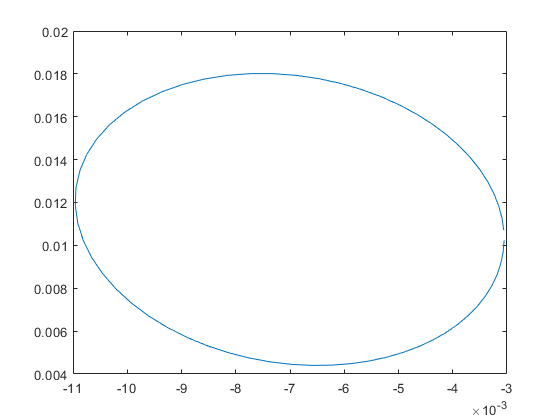

RY = EAAtoRotMatrix(90, [0;1;0]);
RZ = EAAtoRotMatrix(-20, [0;0;1]);

%matriu que relaciona càmera amb món (món-càmera)
cRw = RY' * RZ';

%vector origen món vist des de la càmera
CoW = -cRw * wc;

cAw = [cRw CoW; 0 0 0 1];
camera_fl = 1/34;
circle_points = cameraproj(cAw, camera_fl, A);
plot(circle_points(1,:),circle_points(2,:));

##  3.2 Make also a 3D plot where all the scene is drawn in the world coordinates. The scene must contain the 2 reference frames (2 orthogonal sets of vectors) and the circle points. 

%

You can use the provided function cameraproj.

# Exercise 4:

The columns of the next matrix, represents the coordinates od 4 points defined in a world frame.

A = load('AEx4.mat');
A = A.A;

From this 4 points, two segments are defined. The segment one, goes from the point defined by the first column to the point defined by the second column. The second segment is defined by the other two points.

 A camera frame is seeing the scene. The origin of the world frame seen from the camera frame is given by the vector

wc = [4.665;3.735;-0.5395];

And the orientation of the camera frame is obtained after rotating the world frame -150 degs about the direction

u = [0.01;-.2;1];

With the data provided determine:

## 4.1 The minimum angle that both segments forms (hint, they intersect)

s1 = A(:,2)-A(:,1);
s2 = A(:,4)-A(:,3);

ang1 = acosd((dot(s1,s2) / (norm(s1) * norm(s2))))

ang1 = 53.1301

%al tallarse els segments formen 4 angles. 2 d'ells són iguals entre ells i els altres 2, iguals entre ells també.
%per tant, per trobar l'altre angle caldrà fer:

ang2 = (360 - 2 * ang1) / 2

ang2 = 126.8699

%els 4 angles han de sumar 360 graus
comprovation = ang1 * 2 + ang2 * 2

comprovation = 360


%l'angle més petit és de 53.1301 graus (ang1)

## 4.2 The angle that both segments forms in the image plane

%matriu que relaciona càmera amb món (món-càmera)

cRw = EAAtoRotMatrix(-150, u);

%matriu afí

cAw = [cRw wc; 0 0 0 1];

points = cameraproj(cAw, 1/34, A);

s1 = points(:,2)-points(:,1);
s2 = points(:,4)-points(:,3);

%angles

ang1 = acosd((dot(s1,s2) / (norm(s1) * norm(s2))))

ang1 = 64.0264

ang2 = (360 - 2 * ang1) / 2

ang2 = 115.9736


comprovation = ang1 * 2 + ang2 * 2

comprovation = 360


%l'angle més petit és de 64 graus i el més gran és de 115 graus

## 4.3 Deliver a 3D representation of the scene with all the coordinates refered to the world frame

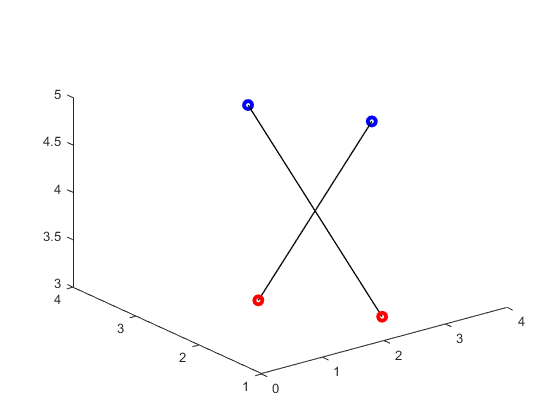

a1 = A(:,1);
a2 = A(:,2);
a3 = A(:,3);
a4 = A(:,4);

plot3([a1(1);a2(1)], [a1(2);a2(2)], [a1(3);a2(3)], 'Color', [0,0,0], 'LineWidth', 1);

hold on;

plot3([a3(1);a4(1)], [a3(2);a4(2)], [a3(3);a4(3)], 'Color', [0,0,0], 'LineWidth', 1);

plot3(a1(1), a1(2), a1(3), 'Marker', 'o', 'Color', [1,0,0], 'LineWidth', 3);
plot3(a3(1), a3(2), a3(3), 'Marker', 'o', 'Color', [1,0,0], 'LineWidth', 3);
plot3(a2(1), a2(2), a2(3), 'Marker', 'o', 'Color', [0,0,1], 'LineWidth', 3);
plot3(a4(1), a4(2), a4(3), 'Marker', 'o', 'Color', [0,0,1], 'LineWidth', 3);

hold off;

## 4.4 Deliver the same 3D scene representations but with all the coordinates refered to the camera frame

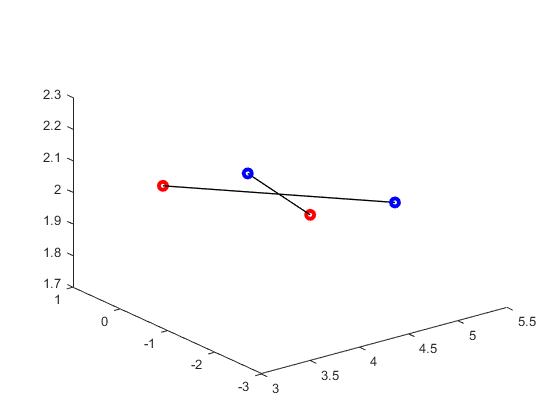

%fem servir matriu afí per trobar coordenades del frame de la càmera
a1 = cAw * [a1;1];
a2 = cAw * [a2;1];
a3 = cAw * [a3;1];
a4 = cAw * [a4;1];

plot3([a1(1);a2(1)], [a1(2);a2(2)], [a1(3);a2(3)], 'Color', [0,0,0], 'LineWidth', 1);

hold on;

plot3([a3(1);a4(1)], [a3(2);a4(2)], [a3(3);a4(3)], 'Color', [0,0,0], 'LineWidth', 1);

plot3(a1(1), a1(2), a1(3), 'Marker', 'o', 'Color', [1,0,0], 'LineWidth', 3);
plot3(a3(1), a3(2), a3(3), 'Marker', 'o', 'Color', [1,0,0], 'LineWidth', 3);
plot3(a2(1), a2(2), a2(3), 'Marker', 'o', 'Color', [0,0,1], 'LineWidth', 3);
plot3(a4(1), a4(2), a4(3), 'Marker', 'o', 'Color', [0,0,1], 'LineWidth', 3);

hold off;